NMY_st.name='NMY'; 
NMY_st.lat=-70.665;
NMY_st.lon=-8.27;
NMY_st.alt=42;
NMY_st.env='P';
NMY_st.footp='Mx';


NMY_rd=read_betsy('NMY_2001_2017',NMY_st.name);

%read scat 2013
SCAT2013=SCAT2013(2:end,:);
MAAP2014=MAAP2014(2:end,:);

t=datenum([2013 01 01 00 00 00])*ones(8760,1)+SCAT2013.VarName1;
sc13=timetable(datetime (datevec(t)));
sc13.U=SCAT2013.VarName7;
sc13.BsB=SCAT2013.VarName9;
sc13.BsG=SCAT2013.VarName10;
sc13.BsR=SCAT2013.VarName11;
sc13.BbsB=SCAT2013.VarName12;
sc13.BbsG=SCAT2013.VarName13;
sc13.BbsR=SCAT2013.VarName14;
sc13.flag=SCAT2013.VarName27;
ind=sc13.flag==999;
names=fieldnames(sc13);
c=startsWith(names,["B";"U"]);
N=names(c);
for i=1:length (N)
    sc13.(N{i})(ind)=NaN;
    indN=sc13.(N{i})>9999;
    sc1.(N{i})(indN)=NaN;
end
sc13.flag=[];
sc13=retime(sc13,'daily',@nanmedian);

t=datenum([2018 01 01 00 00 00])*ones(8760,1)+SCAT2018.start_time;
sc18=timetable(datetime (datevec(t)));
sc18.U=SCAT2018.RH_int    ;
sc18.BsB=SCAT2018.sc450;
sc18.BsG=SCAT2018.sc550;
sc18.BsR=SCAT2018.sc700;
sc18.BbsB=SCAT2018.bsc450;
sc18.BbsG=SCAT2018.bsc550;
sc18.BbsR=SCAT2018.bsc700;
sc18.flag=SCAT2018.numflag;
ind=sc18.flag==0.999;
names=fieldnames(sc18);
c=startsWith(names,["B";"U"]);
N=names(c);
for i=1:length (N)
    sc18.(N{i})(ind)=NaN;
    indN=sc18.(N{i})>9999;
    sc1.(N{i})(indN)=NaN;
end
sc18.flag=[];
sc18=retime(sc18,'daily',@nanmedian);

t=[datenum([2006 01 01 00 00 00])*ones(8760,1)+MAAP2006.start_time;datenum([2007 01 01 00 00 00])*ones(8760,1)+MAAP2007.start_time;...
    datenum([2008 01 01 00 00 00])*ones(8784,1)+MAAP2008.start_time;datenum([2009 01 01 00 00 00])*ones(8760,1)+MAAP2009.start_time;...
    datenum([2010 01 01 00 00 00])*ones(8760,1)+MAAP2010.start_time;...
    datenum([2011 01 01 00 00 00])*ones(8760,1)+MAAP2011.start_time;...
    datenum([2012 01 01 00 00 00])*ones(8784,1)+MAAP2012.start_time;datenum([2013 01 01 00 00 00])*ones(8760,1)+MAAP2013.start_time;...
    datenum([2014 01 01 00 00 00])*ones(8760,1)+MAAP2014.start_time;datenum([2015 01 01 00 00 00])*ones(8760,1)+MAAP2015new.start_time;...
    datenum([2016 01 01 00 00 00])*ones(8784,1)+MAAP2016new.start_time;datenum([2017 01 01 00 00 00])*ones(8760,1)+MAAP2017.start_time;...
    datenum([2018 01 01 00 00 00])*ones(8760,1)+MAAP2018.start_time];
maap=timetable(datetime (datevec(t)));

maap.BaR=[MAAP2006.aerosol_absorption_coefficient;MAAP2007.aerosol_absorption_coefficient;MAAP2008.aerosol_absorption_coefficient;...
    MAAP2009.aerosol_absorption_coefficient;MAAP2010.aerosol_absorption_coefficient;MAAP2011.aerosol_absorption_coefficient;...
    MAAP2012.aerosol_absorption_coefficient;MAAP2013.aerosol_absorption_coefficient;MAAP2014.aerosol_absorption_coefficient; MAAP2015new.abs637;...
    MAAP2016new.abs637;MAAP2017.abs637;MAAP2018.abs637];
maap.flag=[MAAP2006.numflag;MAAP2007.numflag;MAAP2008.numflag;MAAP2009.numflag;MAAP2010.numflag;MAAP2011.numflag;...
    MAAP2012.numflag;MAAP2013.numflag;MAAP2014.numflag;MAAP2015new.numflag;MAAP2016new.numflag;MAAP2017.numflag;MAAP2018.numflag];


ind=maap.flag==999; 
    indN=maap.BaR>999999;
    maap.BaR(indN)=NaN;
       maap.BaR(ind)=NaN;
   maap=retime(maap,'daily',@nanmedian);
   

% pp=timerange('2006-01-01','2019-01-01');
% NMY_rd.BaR_A(pp)=maapo.BaR;
NMY_rd=synchronize(NMY_rd,maap);
NMY_rd.BaR_A=NMY_rd.BaR;
NMY_rd.BaR=[];
NMY_rd.flag=[];
% pp2=timerange('2017-01-01','2018-01-01');
% NMY_rd.BaR_A(pp2)=NMY_rd.Ba_A(pp2);

Error using tabular/dotParenReference (line 69)
Unrecognized table variable name 'Ba'.

% NMY_rd.Ba_A=[];

    pp3=timerange('2013-01-01','2014-01-01');
NMY_rd.BsB_S(pp3)=sc13.BsB;
NMY_rd.BsG_S(pp3)=sc13.BsG;
NMY_rd.BsR_S(pp3)=sc13.BsR;
NMY_rd.BbsB_S(pp3)=sc13.BbsB;
NMY_rd.BbsG_S(pp3)=sc13.BbsG;
NMY_rd.BbsR_S(pp3)=sc13.BbsR;

    pp4=timerange('2018-01-01','2019-01-01');
NMY_rd.BsB_S(pp4)=sc18.BsB;
NMY_rd.BsG_S(pp4)=sc18.BsG;
NMY_rd.BsR_S(pp4)=sc18.BsR;
NMY_rd.BbsB_S(pp4)=sc18.BbsB;
NMY_rd.BbsG_S(pp4)=sc18.BbsG;
NMY_rd.BbsR_S(pp4)=sc18.BbsR;

datevec(NMY_rd.Time(1))

ans =         2001           1           2           0           0           0


datevec(NMY_rd.Time(end))

ans =         2018          12          31           0           0           0


prctile(NMY_rd.U_S,[5 50 95])

ans =          0    1.9500   10.4500


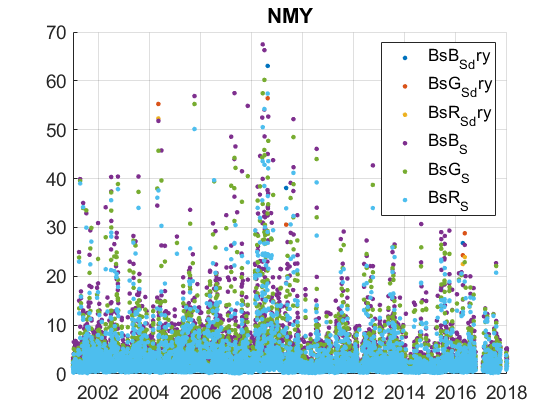

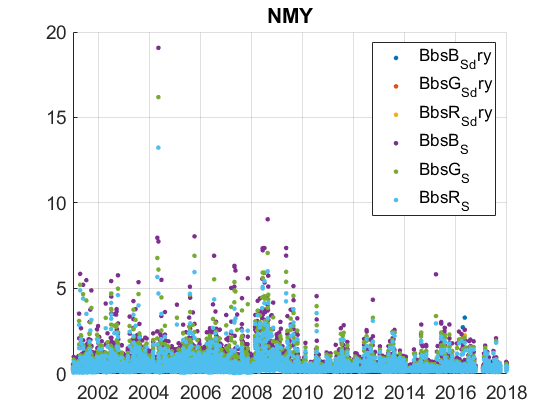

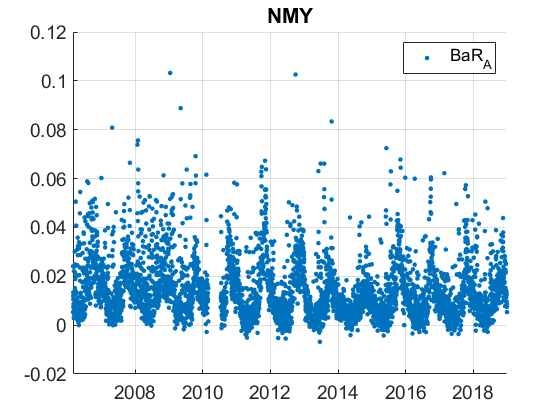

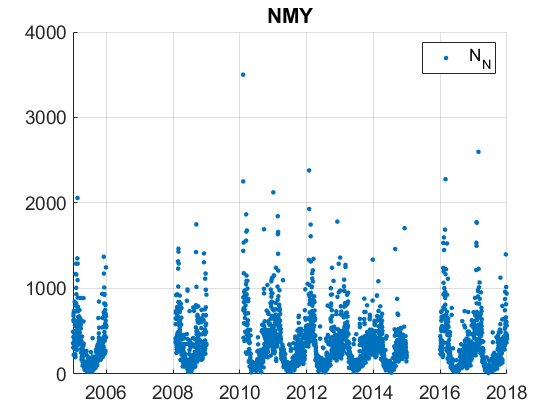

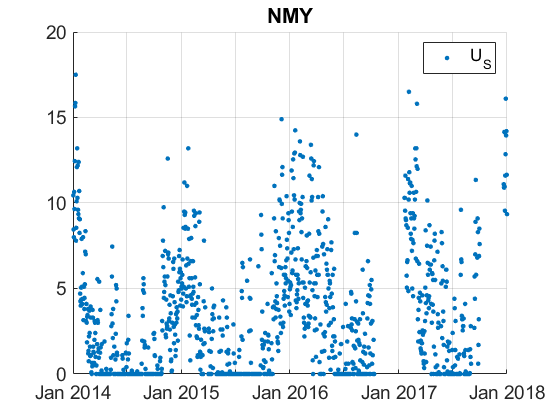

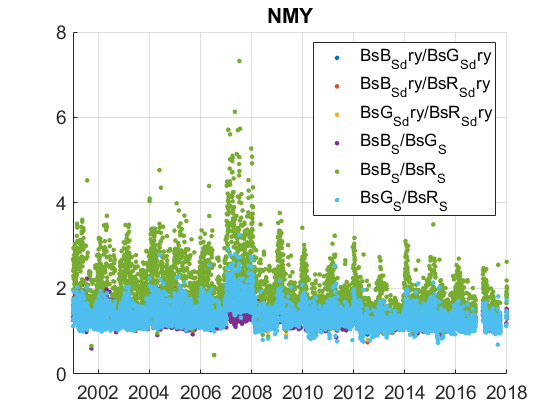

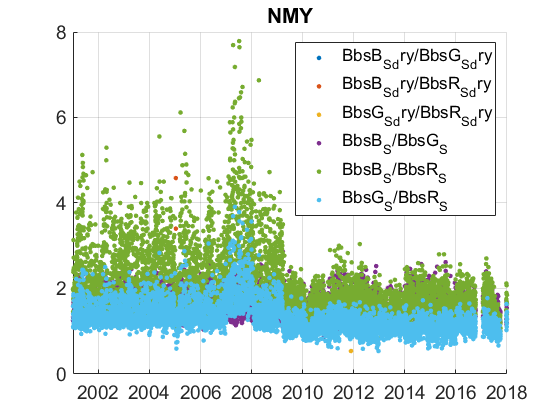

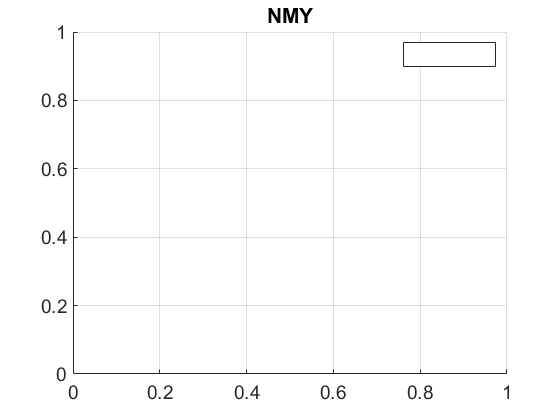

NMY_rd.BsB_S(NMY_rd.BsB_S>4000)=NaN;
NMY_rd.BsG_S(NMY_rd.BsG_S>4000)=NaN;
NMY_rd.BsR_S(NMY_rd.BsR_S>4000)=NaN;

NMY_rd.BbsB_S(NMY_rd.BbsB_S>4000)=NaN;
NMY_rd.BbsG_S(NMY_rd.BbsG_S>4000)=NaN;
NMY_rd.BbsR_S(NMY_rd.BbsR_S>4000)=NaN;
plotFigControl(NMY_rd,NMY_st.name);

% 1 size cut, ok
% sc: ok, so clear season, no negatives
% abs: so clear season, few negatives


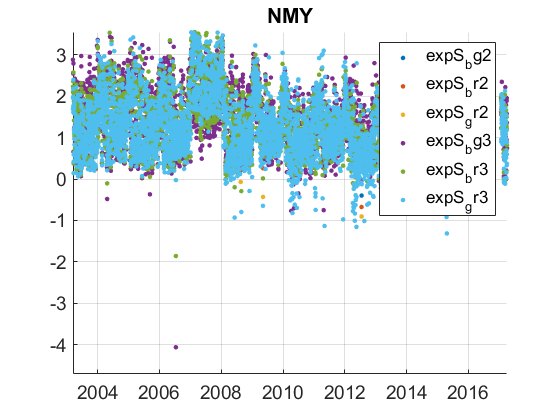

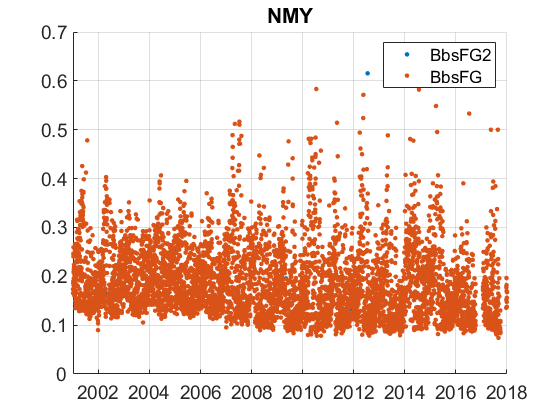

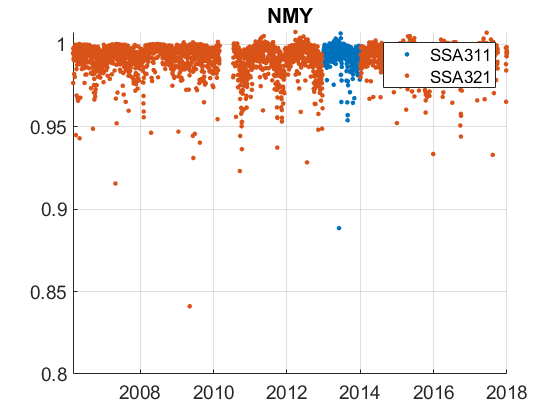

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
NMY_cal=compute_exp_SSA(NMY_rd,lambdaSC, lambdaAE);
plotFigControl_cal(NMY_cal, NMY_st.name);

%Questions:
%problems:
%scat: 2013 is missing
%scat: strange increase of minima in 2008 followed by a decrease of the minima in March 2009: do you know what happened ?
% scat: aftre march 2009, the minima are lower. This is also visible in the backscattering
% scat: the ratio BsB/BsR and BsG/BsR are clearly higher from January 2007 to feb 2008: What happened ? is it a data submission problem or an instrumental problem ?
% idem for the backscattering and the exponent.
% scat: the change in minima value with lower values after 2010 is visible in the scat/N ratio
% the backscattering fraction (BbsF) has higher maxima since 2007 and lower minima since 2010 (continuous decrease from 2007 to 2010). Is this real or could be explained by intrumental changes ?

%abs: 2014-2015 are missing
%abs: 2017 is considered as another time series (fragmentation problems)
%abs: instrument resolution: 0.01 Mm-1 (still visible after daily aggregation?)

%N: 2006-7, 2009 and 2015 missing. Clear seasonal cycle with max in winter


NMY_tr=NMY_rd; 
NMY_tr.y=year(NMY_tr.Time);
%begin 24.3.2009 sc and  1.1.2007 abs
%end: 2018
P=timerange('2007-01-01','2019-01-01');
NMY_tr=NMY_tr(P,:);

% %U very low --> no trend in U and dry
names=fieldnames(NMY_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"U";"flag"]) | endsWith(names,'dry') | contains(names,'Q');
N=names(c);
for i=1:length(N)
    NMY_tr.(N{i})=[];
end

%neph since 24.3.2009
P1=timerange('2007-01-01','2009-03-24');
NMY_tr.BsB_S(P1)=NaN;
NMY_tr.BsG_S(P1)=NaN;
NMY_tr.BsR_S(P1)=NaN;
NMY_tr.BbsB_S(P1)=NaN;
NMY_tr.BbsG_S(P1)=NaN;
NMY_tr.BbsR_S(P1)=NaN;

%correct abs for green wavelength to compute SSA
NMY_tr.BaR_A=NMY_tr.BaR_A.*(637/550);
NMY_cal2=compute_exp_SSA(NMY_tr,lambdaSC, lambdaAE);

NMY_tr=outerjoin(NMY_tr, NMY_cal2);

%compute trend only on G
NMY_tr.BsB_S=[];
NMY_tr.BsR_S=[];
NMY_tr.BbsB_S=[];
NMY_tr.BbsR_S=[];


% expS only on bg
NMY_tr.expS_br3=[];
NMY_tr.expS_gr3=[];

NMY_result= all_trend_STN(NMY_tr,NMY_st); 
plot_10y_in_two(NMY_result, NMY_st);

NMY_result_D=NMY_result;